remove bTrainingWithValidation ;

train = 80%

validatiion = 15%

test = 5%

use dividerand

clear ;
close all;

load ryan2_gen_data.mat

 i


idx = idxAll 

idx =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


x_input_size = 100;

y = [battery_dataset(idx).cycle_life ]';
x = (reshape([battery_dataset(idx).Ic],x_input_size,length(y)))';

[ynorm,xnorm] = norm_with(y,x,ymax,ymin,xmax,xmin);


FNN 으로 테스트 - training set (test/validation 없이 )

feedforwardnet([50,10] => 2개충, 첫번째 50 뉴런, 두번째층 10 개 뉴런

=== 참조 ==

`hiddenSizes` **—** **Size of the hidden layers**

10 (default) | row vector

Size of the hidden layers in the network, specified as a row vector. The length of the vector determines the number of hidden layers in the network.

**Example:** For example, you can specify a network with 3 hidden layers, where the first hidden layer size is 10, the second is 8, and the third is 5 as follows: `[10,8,5]`

The input and output sizes are set to zero. The software adjusts the sizes of these during training according to the training data.

**Data Types:** `single` | `double`

[https://kr.mathworks.com/matlabcentral/answers/260613-validation-sets-vs-test-sets](https://kr.mathworks.com/matlabcentral/answers/260613-validation-sets-vs-test-sets)

`Total     = Design + Nondesign`

` Design    = Training + Validation`

` Nondesign = Testing`

` Total       = Training + Nontraining`

` Nontraining = Validation + Testing`

` Overfitting: Using more ``weights and biases than necessary`

` Overtraining: Improving the ``performance of the training data at the expense of deteriorating the performance`

` on ``nontraining data`

` Training ``data subset: Used to DIRECTLY estimate weights and biases. Performance estimates are BIASED.`

` Validation ``data subset: Used to `

` (1) determine ``when overtraining an overfit net begins to occur AND `

` (2) rank ``multiple designs. `

` Performance ``estimates are SIGNIFICANTLY LESS BIASED than training data estimates.`

` Test data subset: Used to obtain UNBIASED ESTIMATES of performance on nontraining (INCLUDING UNSEEN!) data`

[https://kr.mathworks.com/help/deeplearning/ref/dividerand.html](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html)

`[`[`trainInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_1728d793-edc6-4595-8a0d-22992dffe813)`,`[`valInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_caf766f1-5912-45f0-919e-f903b9d313f4)`,`[`testInd`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_8e6cbc0b-a46a-4dbf-b95c-5eb6fcd46e9b)`] = dividerand(`[`Q`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_a6062bcf-a3b1-4224-9caa-fa872fae85d3)`,`[`trainRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_72c9b34e-a329-46f2-a907-39b169c6e19a)`,`[`valRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_2abef95f-2bd8-4aec-8a09-126cd5c93bcc)`,`[`testRatio`](https://kr.mathworks.com/help/deeplearning/ref/dividerand.html#mw_f4192d38-e08b-446c-af8a-ee0cc9472af8)`)`는 나눌 목표값의 개수, 훈련에 사용할 벡터의 비율, 검증에 사용할 벡터의 비율, 테스트에 사용할 벡터의 비율을 받고, 훈련 인덱스, 검증 인덱스, 테스트 인덱스를 반환합니다

[https://kr.mathworks.com/help/deeplearning/ug/divide-data-for-optimal-neural-network-training.html](https://kr.mathworks.com/help/deeplearning/ug/divide-data-for-optimal-neural-network-training.html)

훈련, 테스트 및 검증의 디폴트 비율은 각각 0.7, 0.15, 0.15입니다.

[https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html](https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html)

베이즈 정규화는 함수 [`trainbr`](https://kr.mathworks.com/help/deeplearning/ref/trainbr.html)에 구현되어 있습니다. 다음 코드는 이 함수를 사용하여 1-20-1 신경망이 [얕은 신경망 일반화를 개선하고 과적합 방지하기](https://kr.mathworks.com/help/deeplearning/ug/improve-neural-network-generalization-and-avoid-overfitting.html) 항목의 그림에 나와 있는 잡음이 있는 사인파를 근사하도록 훈련시키는 방법을 보여줍니다. ([`trainbr`](https://kr.mathworks.com/help/deeplearning/ref/trainbr.html)의 영향이 조기 중지로부터 격리되도록 `net.divideFcn`을 설정하여 데이터 분할이 취소되었습니다.)

`x = -1:0.05:1;`

`t = sin(2*pi*x) + 0.1*randn(size(x));`

`net = feedforwardnet(20,'trainbr');`

`net = train(net,x,t);`

- FNN with 10 hidden neurons.


netFNN1_v4 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_v4.divideFcn = 'divideind'

netFNN1_v4 =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 10
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      in

%netFNN1_v4.divideParam
%netFNN1_v4.divideMode
% dividerand 는 아래의 문제가 있음. 재현시마다 다른 결과 .
%https://kr.mathworks.com/matlabcentral/answers/22100-neural-network-reproducibility-of-results-using-neural-networks-without-initfcn-rands

%netFNN1_v4.divideFcn = 'dividerand';
%netFNN1_v4.divideParam.trainRatio = trainRatio;
%netFNN1_v4.divideParam.valRatio = valRatio;
%netFNN1_v4.divideParam.testRatio = testRatio; 

netFNN1_v4.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN1_v4.divideParam.trainInd = idxTrainRand;
netFNN1_v4.divideParam.valInd = idxValidRand;
netFNN1_v4.divideParam.testInd = idxTestRand; 
    
%netFNN1_v4.divideParam

netFNN1_v4.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_v4, tr] = train(netFNN1_v4, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


tr

tr = struct with fields:
        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'divideind'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×96 double]
          valInd: [2 7 55 56 69 71 93 97 99 104 113]
         testInd: [9 15 20 30 45 46 49 65 79 82 114 116]
            stop: 'Validation stop.'
      num_epochs: 9
       trainMask: {[1×119 double]}
         valMask: {[1×119 double]}
        testMask: {[1×119 double]}
      best_epoch: 3
            goal: 0
          states: {'epoch'  'time'  'perf'  'vperf'  'tperf'  'mu'  'gradient'  'val_fail'}
           epoch: [0 1 2 3 4 5 6 7 8 9]
            time: [0.9230 1.7620 1.9040 1.9700 2.0700 2.1830 2.2830 2.3640 2.4450 2.5280]
            perf: [0.3749 0.0205 0.0070 0.0033 0.0014 0.0010 7.9476e-04 6.7555e-04 5.8500e-04 5.1058e-04]
           vperf: [0.2721 0.0151 0.0152 0.0132 0.0149 0.0154 0.0173 


netFNN2_v4 = feedforwardnet([50,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
%netFNN2_v4
%netFNN2_v4.divideParam

% dividerand 의 경우 동일한 항목으로 train하지 않는다.
% netFNN2_v4.divideFcn = 'dividerand';
% netFNN2_v4.divideParam.trainRatio = trainRatio;
% netFNN2_v4.divideParam.valRatio = valRatio;
% netFNN2_v4.divideParam.testRatio = testRatio; 
% netFNN2_v4.divideParam
netFNN2_v4.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN2_v4.divideParam.trainInd = tr.trainInd;
netFNN2_v4.divideParam.valInd = tr.valInd;
netFNN2_v4.divideParam.testInd = tr.testInd; 

netFNN2_v4.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_v4.trainParam.show = NaN;
[netFNN2_v4, tr2] = train(netFNN2_v4, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN2_v4)
netFNN2_v4

netFNN2_v4 =

    Neural Network
 
              name: 'Feed-Forward Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 5571
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      

tr2

tr2 = struct with fields:
        trainFcn: 'trainlm'
      trainParam: [1×1 struct]
      performFcn: 'mse'
    performParam: [1×1 struct]
        derivFcn: 'defaultderiv'
       divideFcn: 'divideind'
      divideMode: 'sample'
     divideParam: [1×1 struct]
        trainInd: [1×96 double]
          valInd: [2 7 55 56 69 71 93 97 99 104 113]
         testInd: [9 15 20 30 45 46 49 65 79 82 114 116]
            stop: 'Validation stop.'
      num_epochs: 10
       trainMask: {[1×119 double]}
         valMask: {[1×119 double]}
        testMask: {[1×119 double]}
      best_epoch: 4
            goal: 0
          states: {'epoch'  'time'  'perf'  'vperf'  'tperf'  'mu'  'gradient'  'val_fail'}
           epoch: [0 1 2 3 4 5 6 7 8 9 10]
            time: [0.0390 2.4040 6.5640 10.8630 15.1180 19.5410 29.9380 40.7230 45.3240 48.6200 51.3350]
            perf: [0.2009 0.0239 0.0096 0.0040 7.8802e-04 3.3104e-04 1.9907e-04 1.2803e-04 1.0670e-04 2.1809e-05 2.5385e-09]
           vperf: [0.1414 0.0

netFNN3_v4 = feedforwardnet([100,50,10]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_v4.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent
netFNN3_v4.divideParam.trainInd = tr.trainInd;
netFNN3_v4.divideParam.valInd = tr.valInd;
netFNN3_v4.divideParam.testInd = tr.testInd; 

netFNN3_v4.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_v4.trainParam.show = NaN;
netFNN3_v4 = train(netFNN3_v4, xnorm', ynorm', 'useparallel',  'yes');

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


%view(netFNN3_v4)

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:07 |         0.51 |         0.48 |       0.1299 |       0.1145 |          0.0010 |
|      50 |          50 |       00:00:09 |         0.17 |         0.13 |       0.0152 |       0.0079 |          0.0010 |
|     100 |         100 |       00:00:11 |         0.15 |         0.12 |       0.0115 |       0.0073 |          0.0010 |
|     150 |         150 |       00:00:12 |         0.13 |         0.12 |       0.0081 |   

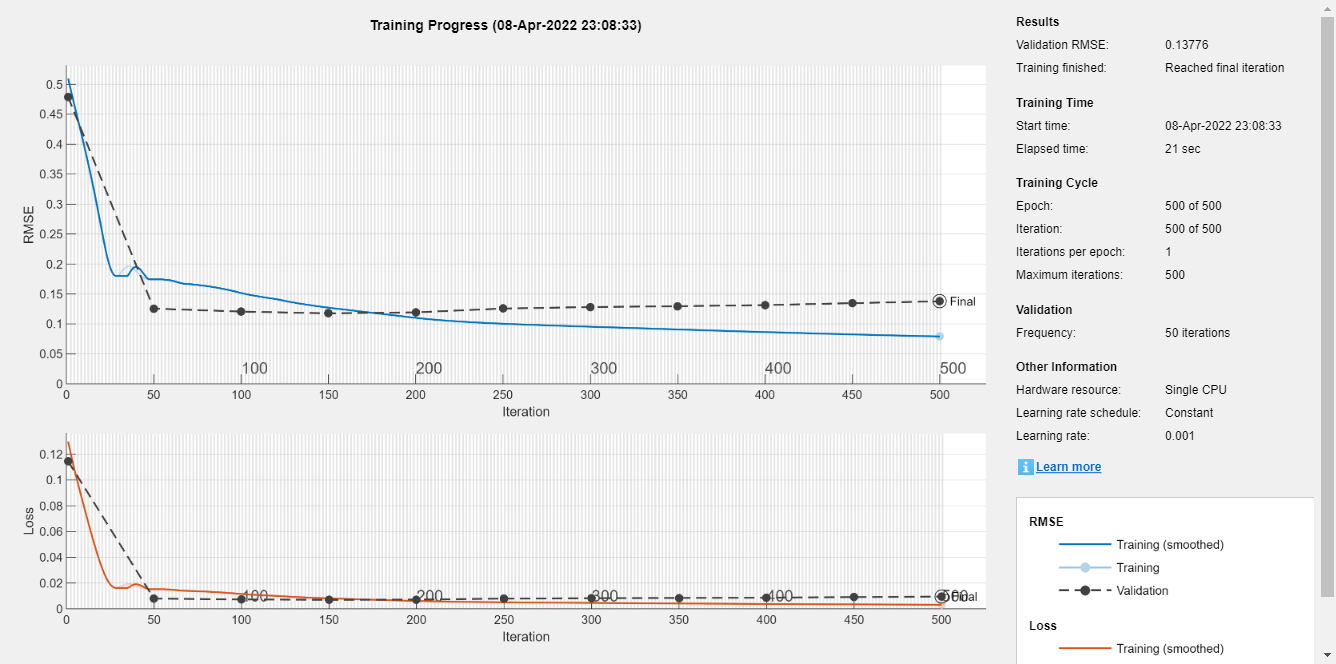

input_size = 100;
layerCNN1 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2], 10, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 5, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];
cellx = num2cell(xnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);

options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',500, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);
 netCNN1_v4 = trainNetwork(Traintbl, layerCNN1, options);



%


- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.32 |         0.30 |       0.0513 |       0.0460 |          0.0010 |
|      50 |          50 |       00:00:06 |         0.11 |         0.13 |       0.0064 |       0.0086 |          0.0010 |
|     100 |         100 |       00:00:07 |         0.09 |         0.14 |       0.0041 |       0.0093 |          0.0010 |
|     150 |         150 |       00:00:09 |         0.08 |         0.14 |       0.0031 |   

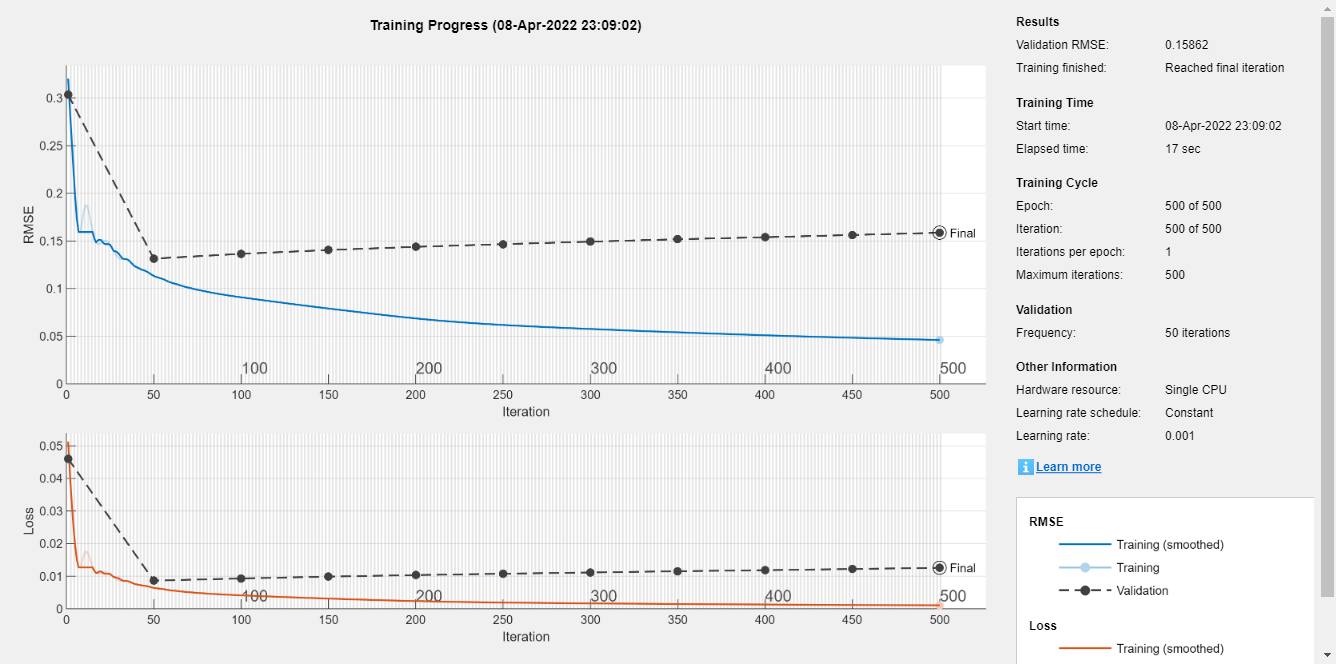

layerCNN2 = [
    imageInputLayer([1, input_size]);
    convolution2dLayer([1, 2], 30, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, 2], 15, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(1)
    regressionLayer();
    ];

netCNN2_v4 = trainNetwork(Traintbl, layerCNN2, options);

- LSTM : 1 lstm layer with 5 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:04 |         0.34 |         0.20 |       0.0588 |       0.0209 |          0.0010 |
|      50 |          50 |       00:00:06 |         0.15 |         0.13 |       0.0117 |       0.0087 |          0.0010 |
|     100 |         100 |       00:00:08 |         0.14 |         0.13 |       0.0100 |       0.0084 |          0.0010 |
|     150 |         150 |       00:00:10 |         0.13 |         0.13 |       0.0086 |       0.0086 |          0.0010 |
|     20

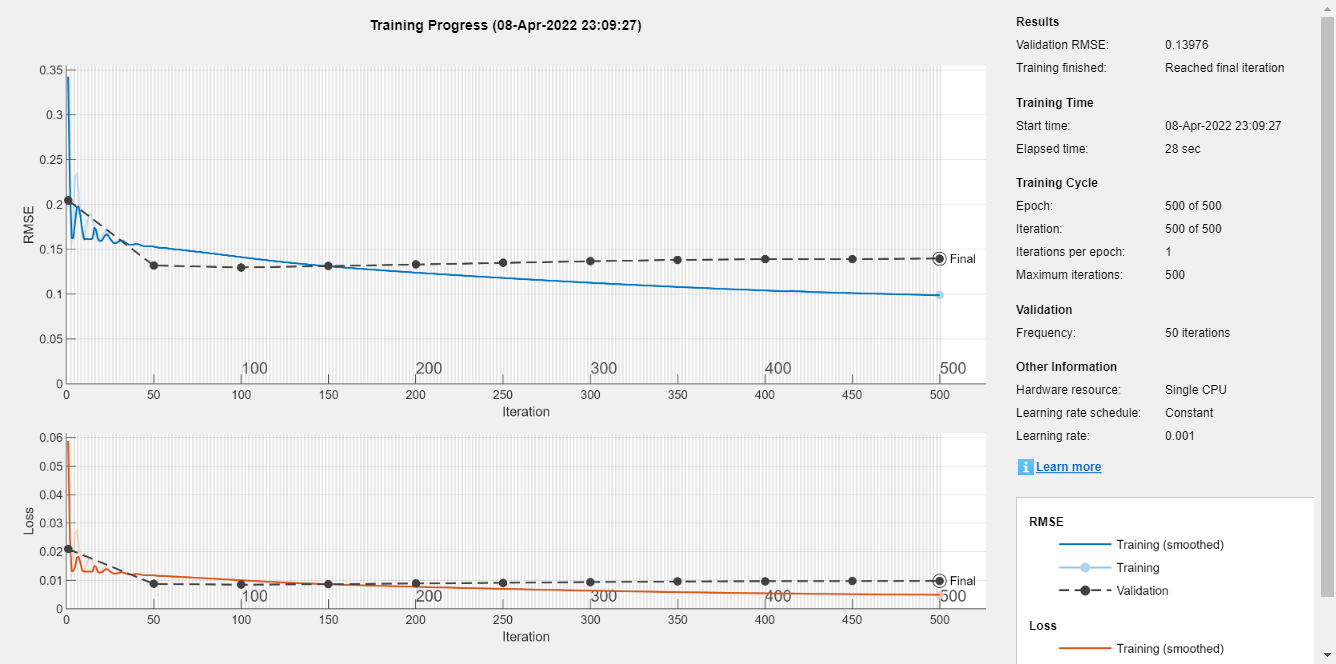

numHiddenUnits = 50;

layersLSTM = [ ...
    sequenceInputLayer(input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm', 1)';
cellyB = num2cell(ynorm);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
     'InitialLearnRate', 0.001, ...
     'MaxEpochs',500, ...
     'MiniBatchSize',50, ...
     'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

    netLSTM_v4 = trainNetwork(traincellx, traincellyB, layersLSTM, options);

%ryan2_gen_data_model_desc = 'ryan2_gen_data_model';
%save('ryan2_gen_data_model.mat','ryan2_gen_data_model_desc');
save('ryan2_gen_data_model.mat','netFNN1_v4' ,'-append')
save('ryan2_gen_data_model.mat','netFNN2_v4' ,'-append')
save('ryan2_gen_data_model.mat','netFNN3_v4' ,'-append')
save('ryan2_gen_data_model.mat','netCNN1_v4' ,'-append')
save('ryan2_gen_data_model.mat','netCNN2_v4' ,'-append')
save('ryan2_gen_data_model.mat','netLSTM_v4' ,'-append')


if bTrainingWithValidation

### Prediciton using each 5 trained model

Make a prediction **using trained models**

- FNN1

pFNN1 = netFNN1_v4(xnorm(tr.testInd, :)');

- FNN40

pFNN = netFNN2_v4(xnorm(tr.testInd, :)');

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

cellx = num2cell(xnorm(tr.testInd, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);

x_4d = zeros(1, input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
pCNN1 = predict(netCNN1_v4, x_4d);

- CNN2 : 2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

pCNN2 = predict(netCNN2_v4, x_4d);

- LSTM : 1 lstm layer with 100 hidden units

pLSTM = cell2mat(predict(netLSTM_v4, num2cell(xnorm(tr.testInd, :)', 1)));

Denormalization for graphical ouput. Multiplying the range of original and add minimum value.

y_real = ynorm(tr.testInd, :)*yrate + ymin;
pFNN1_hat = pFNN1*yrate+ ymin;
pFNN_hat = pFNN*yrate + ymin;
pCNN1_hat = pCNN1*yrate + ymin;
pCNN2_hat = pCNN2*yrate + ymin;
pLSTM_hat = pLSTM*yrate + ymin;

### Result visualization

Visualize the prediction result. Battery capacity estimation based multi-channel charing profiles, using Voltage, Current and temperature.

figure, hold on, grid on,
plot(y_real, 'linewidth', 2), plot(pFNN1_hat, '*--'), plot(pFNN_hat, '^--'), plot(pCNN1_hat, 'o--'), plot(pCNN2_hat, 'x--'), plot(pLSTM_hat, '-.')
%plot(1:25, 1.4*ones(1, 25),'k--','LineWidth', 2), xlim([1 25])
%title(['Capacity Estimation using V, I, T (Battery #', num2str(BatteryNum), ')'])
xlabel Cell
ylabel 'Cycle life'
legend('Real Value', 'FNN1 Predicted', 'FNN Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted')

RMSE

rmse_pFNN1 = sqrt(mean(( y_real' - pFNN1_hat ).^2))
rmse_pFNN = sqrt(mean(( y_real' - pFNN_hat ).^2))
rmse_pCNN1  = sqrt(mean(( y_real' - pCNN1_hat' ).^2))
rmse_pCNN2  = sqrt(mean(( y_real' - pCNN2_hat' ).^2))
rmse_pLSTM  = sqrt(mean(( y_real' - pLSTM_hat' ).^2))
end

ytestnorm_hat_netFNN1 = netFNN1_v4(xtestnorm');
ytestnorm_hat_netFNN2 = netFNN2_v4(xtestnorm');
ytestnorm_hat_netFNN3 = netFNN3_v4(xtestnorm');

total_cycle = length(ytestnorm_hat_netFNN);
cellx = num2cell(xtestnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, x_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end
ytestnorm_hat_netCNN1 = predict(netCNN1_v4, x_4d);
ytestnorm_hat_netCNN2 = predict(netCNN2_v4, x_4d);
ytestnorm_hat_netLSTM = cell2mat(predict(netLSTM_v4, num2cell(xtestnorm', 1)));

ytest_real = ytestnorm*yrate + ymin;
ytest_hat_netFNN1 = ytestnorm_hat_netFNN1*yrate + ymin;
ytest_hat_netFNN2 = ytestnorm_hat_netFNN2*yrate + ymin;
ytest_hat_netFNN3 = ytestnorm_hat_netFNN3*yrate + ymin;
ytest_hat_netCNN1 = ytestnorm_hat_netCNN1*yrate + ymin;
ytest_hat_netCNN2 = ytestnorm_hat_netCNN2*yrate + ymin;
ytest_hat_netLSTM = ytestnorm_hat_netLSTM*yrate + ymin;



RMSE

rmse_ytest_hat_netFNN1 = sqrt(mean(( ytest_real' - ytest_hat_netFNN1 ).^2))

rmse_ytest_hat_netFNN1 = 236.3311

rmse_ytest_hat_netFNN2 = sqrt(mean(( ytest_real' - ytest_hat_netFNN2 ).^2))

rmse_ytest_hat_netFNN2 = 185.5010

rmse_ytest_hat_netFNN3 = sqrt(mean(( ytest_real' - ytest_hat_netFNN3 ).^2))

rmse_ytest_hat_netFNN3 = 244.4806

rmse_ytest_hat_netCNN1 = sqrt(mean(( ytest_real' - ytest_hat_netCNN1' ).^2))

rmse_ytest_hat_netCNN1 = single
229.2495

rmse_ytest_hat_netCNN2  = sqrt(mean(( ytest_real' - ytest_hat_netCNN2' ).^2))

rmse_ytest_hat_netCNN2 = single
365.1465

rmse_ytest_hat_netLSTM  = sqrt(mean(( ytest_real' - ytest_hat_netLSTM' ).^2))

rmse_ytest_hat_netLSTM = single
331.0626

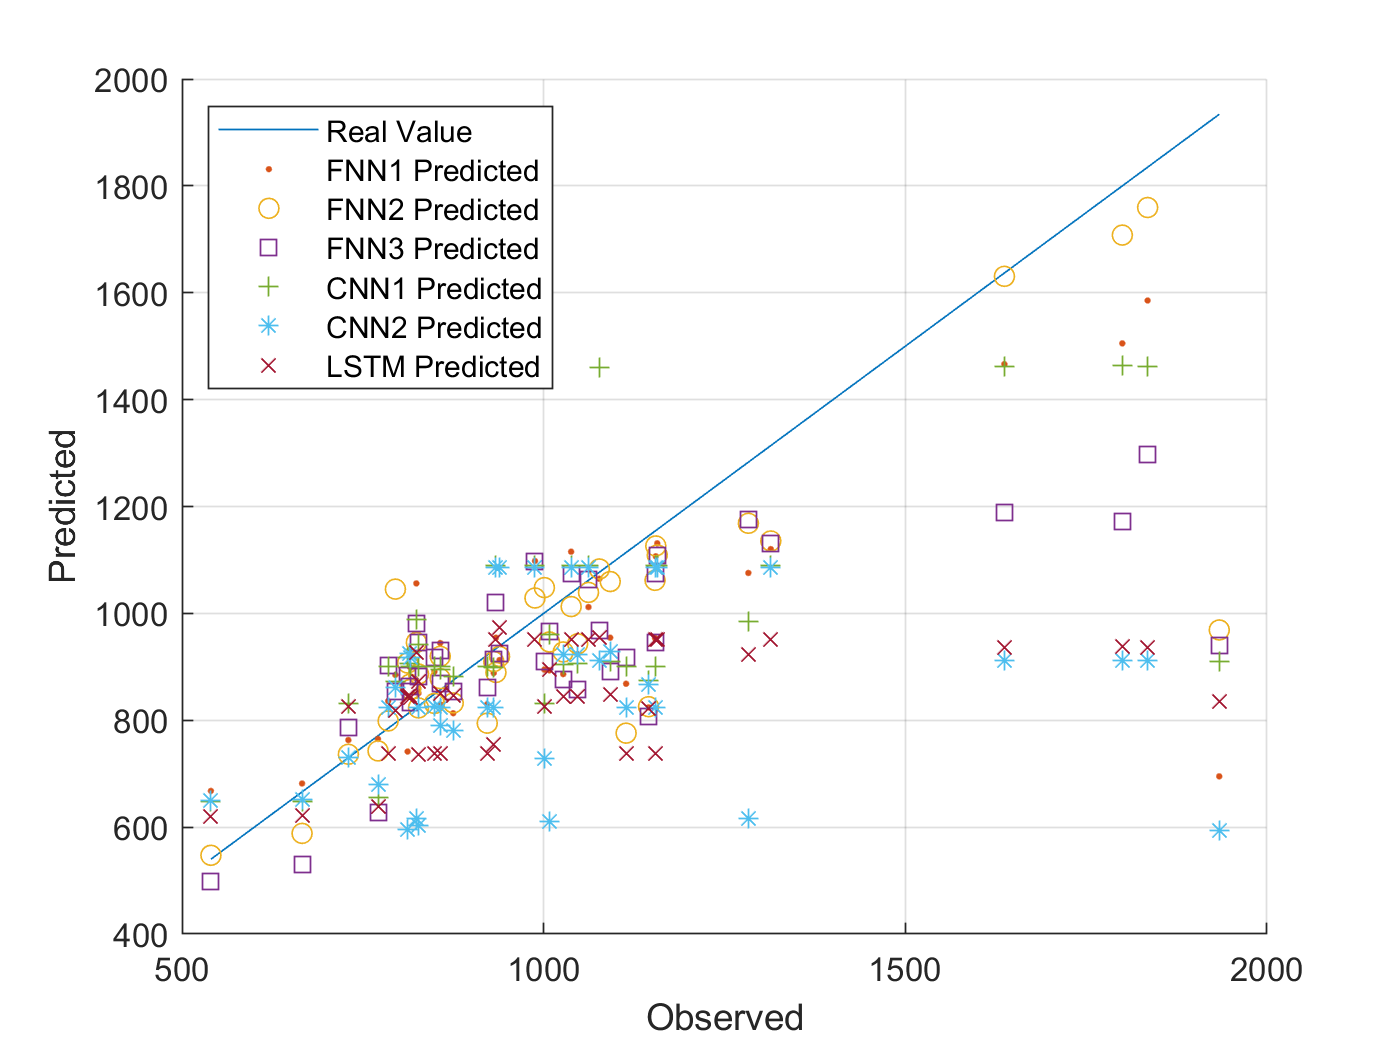


ytest = ytestnorm*yrate + ymin;

figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,ytest_hat_netFNN1,'.')
plot(ytest,ytest_hat_netFNN2,'o')
plot(ytest,ytest_hat_netFNN3,'s')
plot(ytest,ytest_hat_netCNN1,'+')
plot(ytest,ytest_hat_netCNN2,'*')
plot(ytest,ytest_hat_netLSTM,'x')
hold off
xlabel Observed
ylabel Predicted
legend({'Real Value', 'FNN1 Predicted', 'FNN2 Predicted', 'FNN3 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted'},'Location','northwest')

%%여기까지

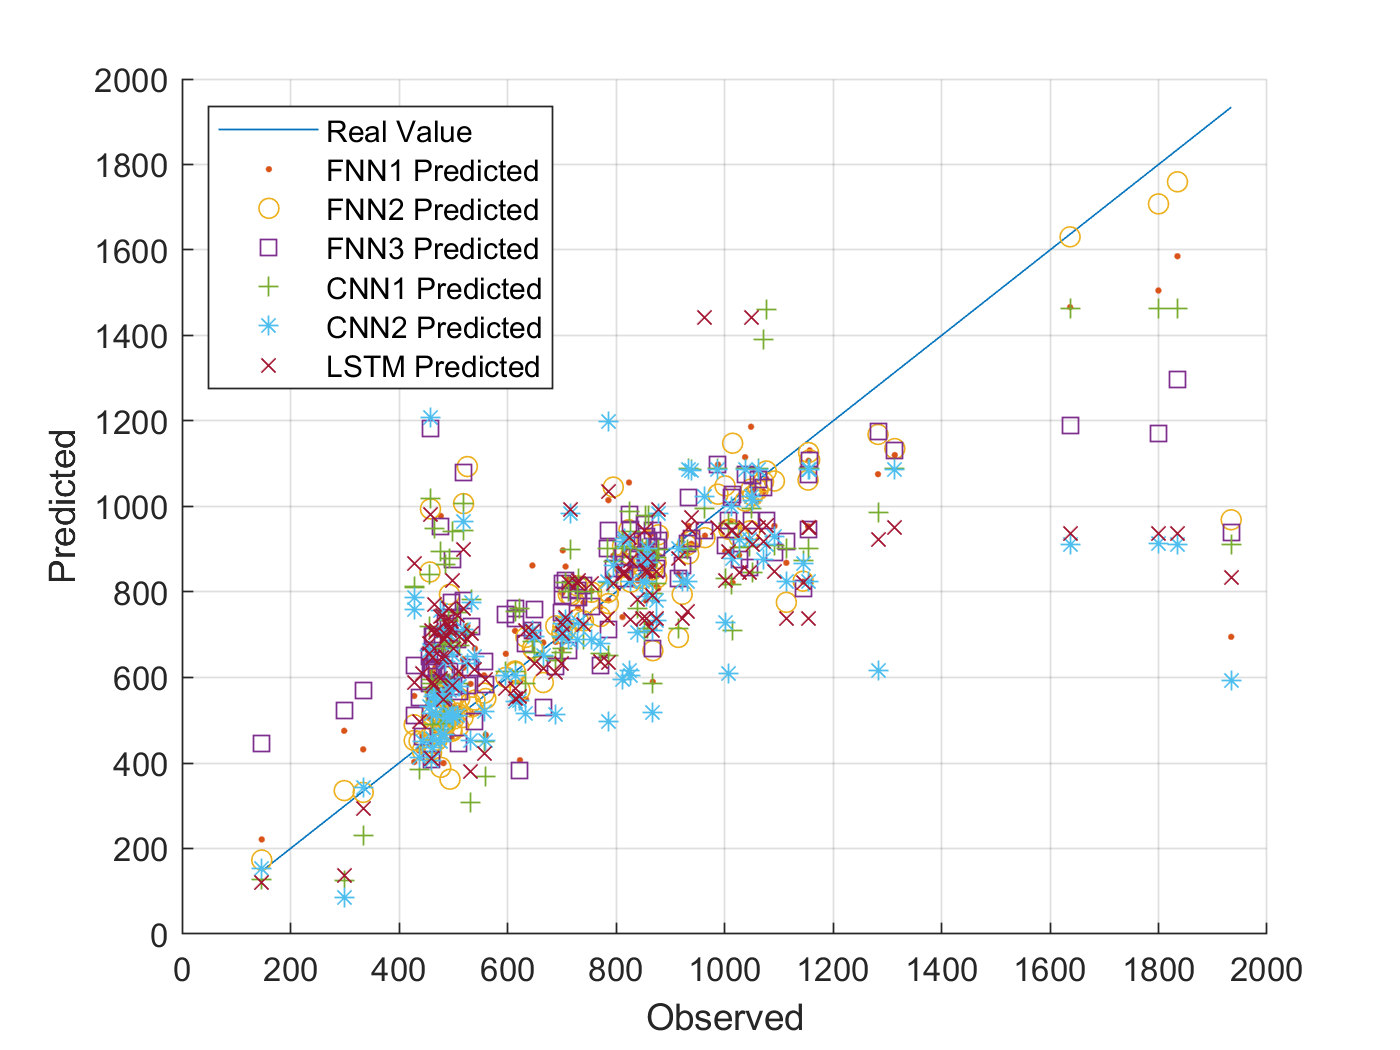


%%%%%%%%%%%% 학습한 데이타로 검증
ynorm_hat_netFNN1_self = netFNN1_v4(xnorm');
ynorm_hat_netFNN2_self = netFNN2_v4(xnorm');
ynorm_hat_netFNN3_self = netFNN3_v4(xnorm');

total_cycle = length(ytestnorm_hat_netFNN);
cellx = num2cell(xnorm', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
tbl = table(cellx);
x_4d = zeros(1, x_input_size, 1, height(tbl));
for i = 1:height(tbl)
    x_4d(:,:,:,i) = tbl.cellx{i};
end

ynorm_hat_netCNN1_self = predict(netCNN1_v4, x_4d);
ynorm_hat_netCNN2_self = predict(netCNN2_v4, x_4d);
ynorm_hat_netLSTM_self = cell2mat(predict(netLSTM_v4, num2cell(xnorm', 1)));


y_self = ynorm*yrate + ymin;

y_hat_netFNN1_self = ynorm_hat_netFNN1_self * yrate + ymin;
y_hat_netFNN2_self = ynorm_hat_netFNN2_self * yrate + ymin;
y_hat_netFNN3_self = ynorm_hat_netFNN3_self * yrate + ymin;
y_hat_netCNN1_self = ynorm_hat_netCNN1_self * yrate + ymin;
y_hat_netCNN2_self = ynorm_hat_netCNN2_self * yrate + ymin;
y_hat_netLSTM_self = ynorm_hat_netLSTM_self * yrate + ymin;


figure, hold on, grid on,
plot(y_self,y)
plot(y_self,y_hat_netFNN1_self,'.')
plot(y_self,y_hat_netFNN2_self,'o')
plot(y_self,y_hat_netFNN3_self,'s')
plot(y_self,y_hat_netCNN1_self,'+')
plot(y_self,y_hat_netCNN2_self,'*')
plot(y_self,y_hat_netLSTM_self,'x')
hold off
xlabel Observed
ylabel Predicted
legend({'Real Value', 'FNN1 Predicted', 'FNN2 Predicted', 'FNN3 Predicted', ...
    'CNN1 Predicted', 'CNN2 Predicted', 'LSTM Predicted'},'Location','northwest')


rmse_y_hat_netFNN1_self  = sqrt(mean(( y_self' - y_hat_netFNN1_self  ).^2))

rmse_y_hat_netFNN1_self = 164.8297

rmse_y_hat_netFNN2_self  = sqrt(mean(( y_self' - y_hat_netFNN2_self  ).^2))

rmse_y_hat_netFNN2_self = 150.4395

rmse_y_hat_netFNN3_self  = sqrt(mean(( y_self' - y_hat_netFNN3_self  ).^2))

rmse_y_hat_netFNN3_self = 205.8528

rmse_y_hat_netCNN1_self  = sqrt(mean(( y_self' - y_hat_netCNN1_self' ).^2))

rmse_y_hat_netCNN1_self = single
214.1582

rmse_y_hat_netCNN2_self  = sqrt(mean(( y_self' - y_hat_netCNN2_self' ).^2))

rmse_y_hat_netCNN2_self = single
251.1002

rmse_y_hat_netLSTM_self  = sqrt(mean(( y_self' - y_hat_netLSTM_self' ).^2))

rmse_y_hat_netLSTM_self = single
246.4197

CNN을 위해 충전전류를 2차원 이미지로 만들기

ynormall,ymax,ymin,yrate,xnormall,xmax,xmin,xrate

%{
a = xtestnorm(1,:)
b = zeros(100,100);
c = round(xtestnorm(1,:)* 100)
for i=1:100
    b(i,c(i)+1)=1;
end
b

xxx = [1:100]

space = [ 1:100]
new_space = [1:28]
new_xxx = interp1(space,xxx,new_space,'linear')
figure
plot(new_xxx)


plot_max_x = 28;
plot_max_y = 28 ;

%a = 
%x = 
xx_max = 28
y_max = 28
rows = max(xtestnorm(1,:));
columns = length(yo);
outputImage = false(rows, columns);
for k = 1 : columns
  outputImage(yo(k), k) = true;
end
imshow(outputImage);
%}